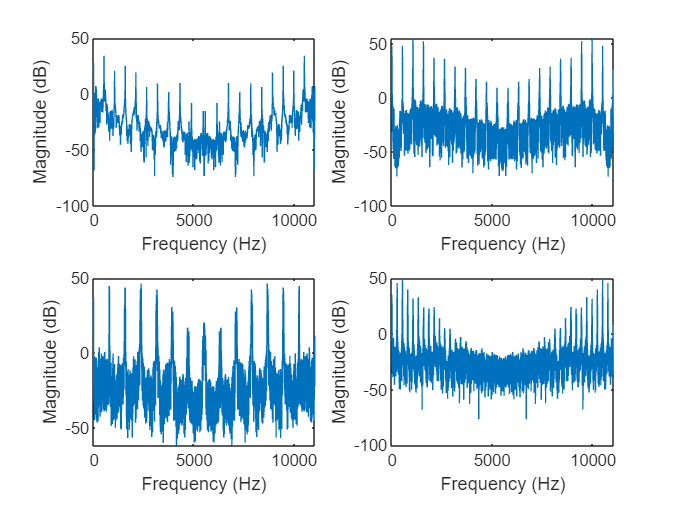

fileNames = {'piano2.wav', 'trumpet2.wav', 'violin2.wav', 'flute2.wav'};
fundamentalFrequencies = zeros(1, numel(fileNames));

for i = 1:numel(fileNames)
    [audioSignal, sampleRate] = audioread(fileNames{i});
    fftResult = fft(audioSignal);
    magnitudeSpectrum = 20*log10(abs(fftResult));
    [~, idx] = max(magnitudeSpectrum);
    fundamentalFrequencies(i) = (idx - 1) * sampleRate / numel(audioSignal);

    subplot(2, 2, i);
    plot((0:(numel(audioSignal)-1)) * sampleRate / numel(audioSignal), magnitudeSpectrum);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
end


instrumentNames = {'Piano', 'Trumpet', 'Violin', 'Flute'};
fprintf('Instrument\tFundamental Frequency (Hz)\n');

Instrument	Fundamental Frequency (Hz)


for i = 1:numel(fileNames)
    fprintf('%s\t\t%.2f\n', instrumentNames{i}, fundamentalFrequencies(i));
end

Piano		523.62
Trumpet		1047.21
Violin		2369.12
Flute		524.33



[pianoAudio, pianoSampleRate] = audioread('piano2.wav');

numFluteSamples = 4;
fluteAudio = cell(1, numFluteSamples);
fundamentalFrequencyFlute = zeros(1, numFluteSamples);

for i = 1:numFluteSamples
    fluteFileName = sprintf('flute%d.wav', i);
    [fluteAudio{i}, fluteSampleRate] = audioread(fluteFileName);
    pianoFFT = fft(pianoAudio);
    fluteFFT = fft(fluteAudio{i});
        [~, pianoIdx] = max(abs(pianoFFT));
    [~, fluteIdx] = max(abs(fluteFFT));
    
    fundamentalFrequencyPiano = (pianoIdx - 1) * pianoSampleRate / numel(pianoAudio);
    fundamentalFrequencyFlute(i) = (fluteIdx - 1) * fluteSampleRate / numel(fluteAudio{i});
end

differences = abs(fundamentalFrequencyFlute - fundamentalFrequencyPiano);
[minDifference, minIndex] = min(differences);

fprintf('Fundamental Frequency (Piano2): %.2f Hz\n', fundamentalFrequencyPiano);

Fundamental Frequency (Piano2): 523.62 Hz


fprintf('Fundamental Frequencies (Flute): %.2f Hz, %.2f Hz, %.2f Hz, %.2f Hz\n', fundamentalFrequencyFlute);

Fundamental Frequencies (Flute): 1063.20 Hz, 524.33 Hz, 793.50 Hz, 524.40 Hz


fprintf('β: %d\n', minIndex);

β: 2


% Record a 3-second snippet of whistling
duration = 3;  % Duration in seconds
fs = 44100;    % Sampling frequency

recObj = audiorecorder(fs, 16, 1);
disp('Start whistling...');
recordblocking(recObj, duration);
disp('End of recording.');

% Save the recorded audio as the reference
reference_audio = getaudiodata(recObj);
audiowrite('reference_whistle.wav', reference_audio, fs);

% Load the recorded whistling audio
[recorded_audio, fs_recorded] = audioread('reference_whistle.wav');

% Compute FFT of the recorded audio
fft_result = fft(recorded_audio);

% Calculate frequency bins
freq_bins = linspace(0, fs_recorded, length(fft_result));

% Calculate magnitude spectrum
magnitude_spectrum = abs(fft_result);

% Find peaks in the magnitude spectrum
[pks, peak_indices] = findpeaks(magnitude_spectrum);

% Plot the magnitude spectrum
figure;
plot(freq_bins, magnitude_spectrum);
hold on;
plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Recorded Whistling');
grid on;

% Find the highest peak frequency
[~, max_peak_index] = max(pks);
fundamental_frequency_recorded = freq_bins(peak_indices(max_peak_index));

fprintf('Fundamental Frequency of Recorded Whistling: %.2f Hz\n', fundamental_frequency_recorded);

% Test case 1: 
checkAccess();

% Test case 2: 
checkAccess();

function checkAccess()
    fs = 44100;  % Sampling frequency
    
    % Record 3-second audio clip
    recObj = audiorecorder(fs, 16, 1);
    disp('Recording...');
    recordblocking(recObj, 3);
    disp('End of recording.');

    % Get the recorded audio
    recorded_audio = getaudiodata(recObj);

    
    % Calculate the fundamental frequency of the recorded audio
    fundamental_frequency_recorded = calculateFundamentalFrequency(recorded_audio, fs);
    
    % Load the reference audio
    [reference_audio, fs_ref] = audioread('reference_whistle.wav');
    
    % Calculate the fundamental frequency of the reference audio
    fundamental_frequency_reference = calculateFundamentalFrequency(reference_audio, fs_ref);
    
    % Define the error tolerance (5%)
    error_tolerance = 0.05 * fundamental_frequency_reference;

    
    % Compare the fundamental frequencies and provide access status
    if abs(fundamental_frequency_recorded - fundamental_frequency_reference) <= error_tolerance
        disp('ACCESS GRANTED');
        plotSpectrum(recorded_audio, fs, 'Test Audio (Access Granted)');
    else
        disp('ACCESS DENIED');
        plotSpectrum(recorded_audio, fs, 'Test Audio (Access Denied)');
    end
end

function fundamental_frequency = calculateFundamentalFrequency(audio, fs)
    % Compute FFT
    fft_result = fft(audio);
    
    % Calculate frequency bins
    freq_bins = linspace(0, fs, length(fft_result));
    
    % Calculate magnitude spectrum
    magnitude_spectrum = abs(fft_result);
    
    % Find peaks in the magnitude spectrum
    [~, peak_indices] = findpeaks(magnitude_spectrum);
    
    % Find the highest peak frequency
    [~, max_peak_index] = max(magnitude_spectrum(peak_indices));
    fundamental_frequency = freq_bins(peak_indices(max_peak_index));
end

function plotSpectrum(audio, fs, titleText)
    % Compute FFT of the audio
    fft_result = fft(audio);
    
    % Calculate frequency bins
    freq_bins = linspace(0, fs, length(fft_result));
    
    % Calculate magnitude spectrum
    magnitude_spectrum = abs(fft_result);
    
    % Find peaks in the magnitude spectrum
    [pks, peak_indices] = findpeaks(magnitude_spectrum);
    
    % Plot the magnitude spectrum
    figure;
    plot(freq_bins, magnitude_spectrum);
    hold on;
    plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(titleText);
    grid on;
end

%q3
[y, fs] = audioread('Opera.wav');

Function definitions in a script must appear at the end of the file.
Move all statements after the "plotSpectrum" function definition to before the first local function definition.

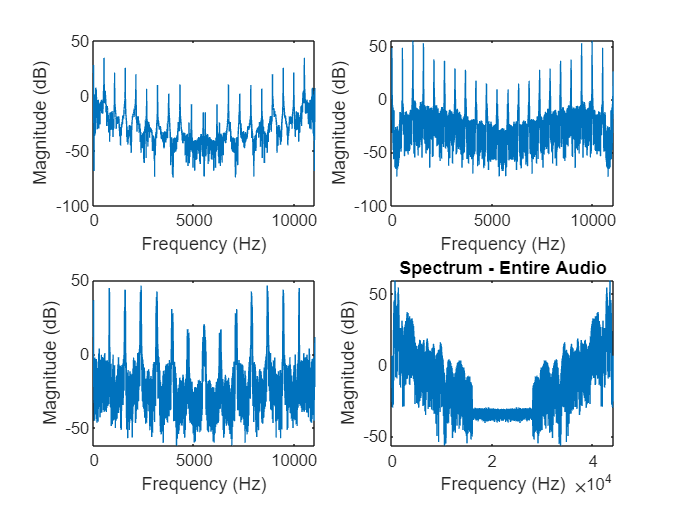


segmentSize = 20000; % Number of samples per segment
numSegments = 11; % Total number of segments

overlap = 0; % No overlap between segments

stepSize = (segmentSize - overlap);
figureCounter = 1;
fullSpectrum = fft(y);
fFull = linspace(0, fs, length(fullSpectrum));

figure(figureCounter);
plot(fFull, 20 * log10(abs(fullSpectrum)));
title('Spectrum - Entire Audio');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

figureCounter = figureCounter + 1; 

[x, fs] = audioread('Opera.wav');

windowSize = 1024;  % Size of the analysis window
overlap = 512;     % Overlap between consecutive windows
nfft = 1024;        % Number of FFT points
[S, F, T] = spectrogram(x, windowSize, overlap, nfft, fs);

'spectrogram' requires Signal Processing Toolbox.


S_dB = 10 * log10(abs(S));

figure;
imagesc(T, F, S_dB);  % Display the spectrogram
axis xy;              % Invert the y-axis to have lower frequencies at the bottom
colormap jet;        % Set the colormap (you can choose different colormaps)
colorbar;            % Add a colorbar to the plot
title('Spectrogram of Opera.wav');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

for i = 1:numSegments
    startIdx = (i - 1) * stepSize + 1;
    endIdx = startIdx + segmentSize - 1;

    segment = y(startIdx:endIdx);
    spectrum = fft(segment);
    f = linspace(0, fs, segmentSize);

    figure(figureCounter);
    plot(f, 20 * log10(abs(spectrum)));
    title(['Spectrum - Segment ', num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    figureCounter = figureCounter + 1;
end